## 1.1 Matlab Signal Processing Onramp

### 1.1.1 Certificate of completion

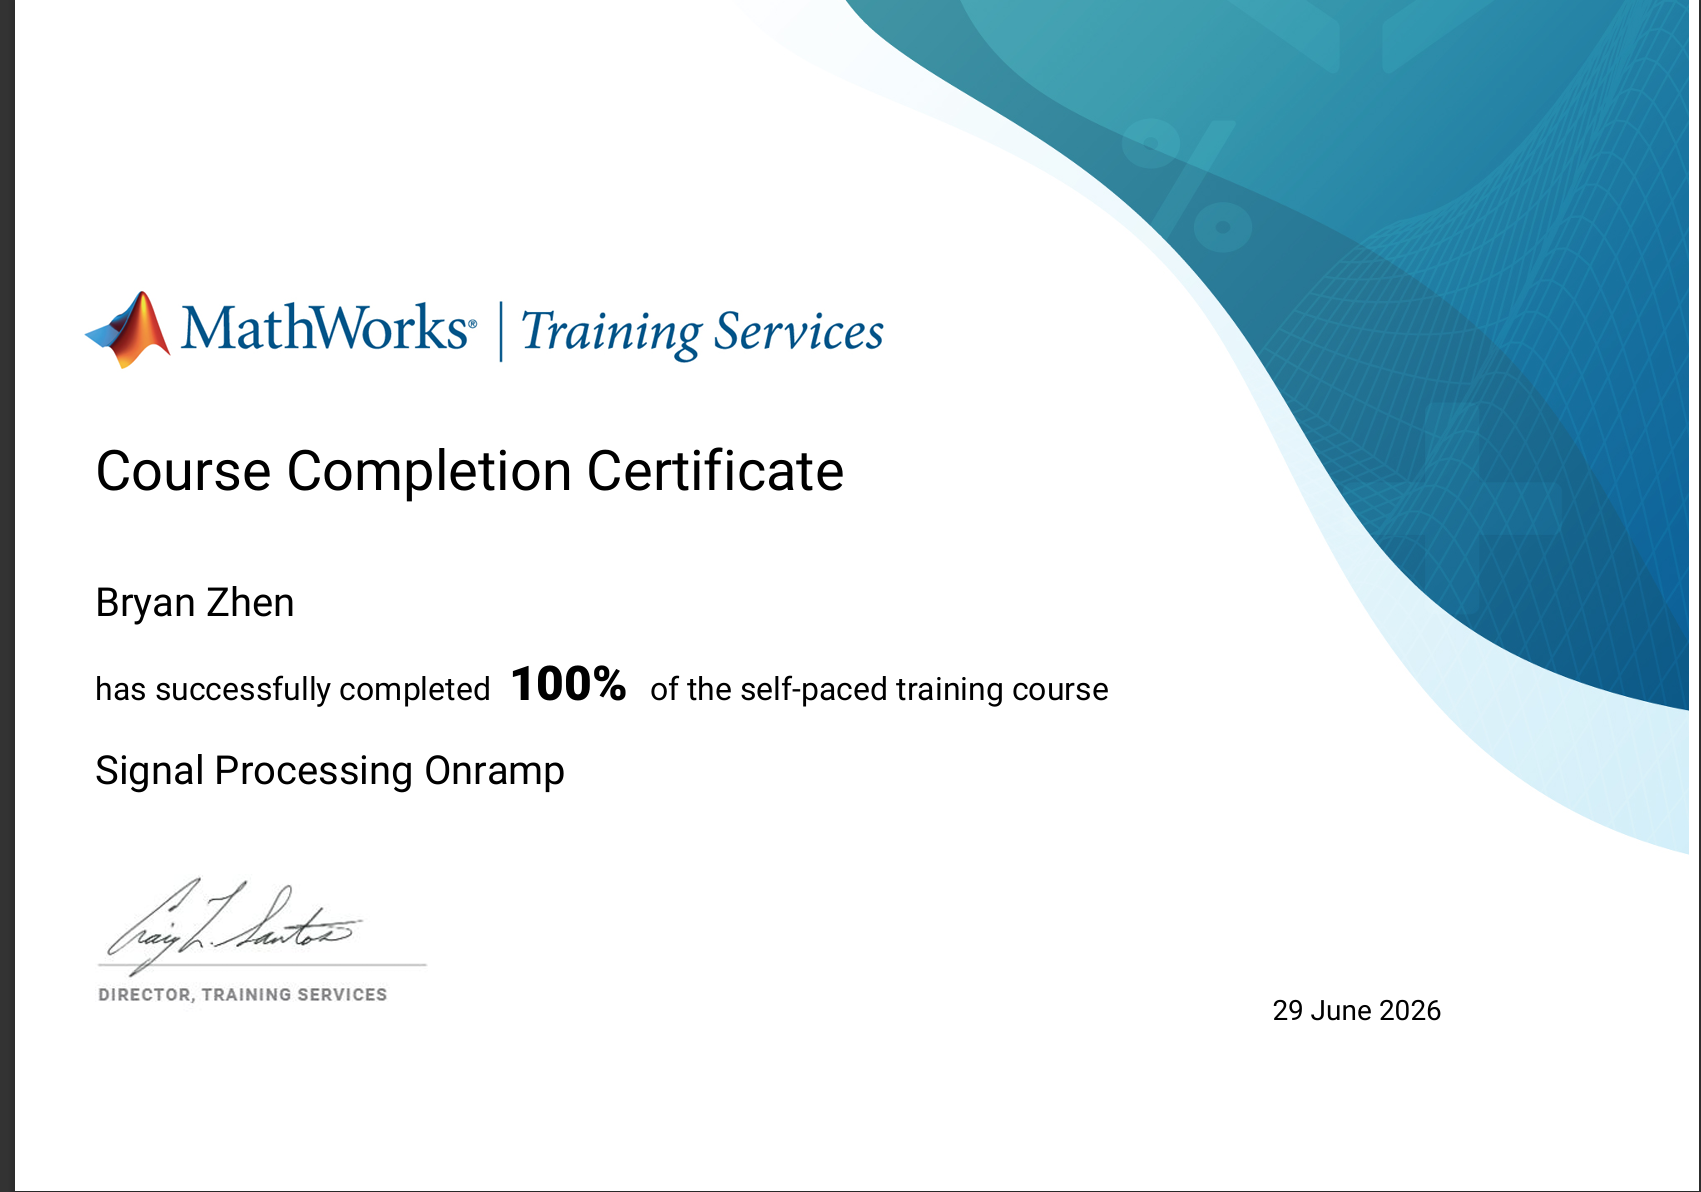

### 1.1.2 Summary and Experience of Onramping

The signal onramping process initially taught me how to set and make my own signals in Matlab code with different frequencies along with how to introduce theoretical noise to my signals. The onramping took a practical example of seismographic earthquake data logged from three stations in Alaska from an earthquake in Sumatra and how to process this data accounting for various factors.

The onramp then taught me how to navigate Matlab’s signal analyzer app, including how to view the signals in the frequency and time domain. I was taught how to adjust the signals based on their time delays and how to display the data neatly by setting boundaries in the viewer for both time and frequency. 

The next section of the lesson also taught me to preprocess my signals in the case of non-uniform sampling, letting us interpolate the signals to new time stamps using resampling. I was taught mainly how to resample signals using a sampling factor or by setting a new frequency. Extracting particular regions of interest using the panner tool in the display tab along with how to extract these regions of interest for display.

Afterwards, I was introduced to how to create custom preprocessing functions and how to export my newly preprocessed signals back into the Matlab workspace. These signals were then realigned to remove the delay such that all three signals used in the example were aligned together in the time domain.

The spectral analysis section of the lesson went further into how to navigate the frequency domain in Matlab’s signal analyzer app. I learned how to scale a signal logarithmically, and how to use time-frequency analysis with spectrograms and scalograms.

Additionally, I was introduced to how to make and use filters in the signal analyzer app in order to filter out unwanted frequencies interfering with my signal analysis. However, I was also cautioned with the tradeoffs of filtering thanks to how it can corrupt the start of a signal.

The signal measurements section explained how to process signals and extract useful data from them in Matlab code.

All in all, I found my experience with this onramping to be fairly straightforward, with the exception of learning how to use the signal analyzer app. The main issue was relatively minor, but occasionally attempting to find what they wanted me to use on the upper toolbar proved to be sometimes a bit difficult without any image references of what exactly I should have been looking for. However, this is generally a fairly minor complaint within a very well-explained and clear course; I especially appreciate the use of a real-world example to help tie the sometimes abstract concept of signal processing into something grounded in reality.

## 2.1 Signal Sampling Code Section

We will first generate a continous-time signal x(t) = sin(2*pi*f0*t), where f0 = 5 Hz.

Since the Frequency of the original signal x(t) is 5 Hz, we know the nyquist frequency of x(t) will be double that value, at 10 Hz.

Although the high-resolution time-step of 0.001 allows us to consider x(t) as practically a continuous signal, this makes its sampling frequency 1000 Hz.

%define variables, signal x(t)
f0 = 5; %signal of x(t) itself
fs0 = 1000;%set sampling frequency
Ts0 = 1/fs0;%set for 0.001 step

t = 0:Ts0:2; 
x = sin(2*pi*f0*t);

We will now resample the original signal x(t) along three different sampling frequencies. the t_new variables will represent the new times where the signal was sampled.

%Define new sampling frequencies
fs1 = 2*f0; %at nyquist f (10Hz)
fs2 = 1.5*f0; %below nyquist f (7.5Hz)
fs3 = 4*f0;%above nyquist f (20Hz)

%resampled signals:
[x1, t1_new] = resample(x,t,fs1);
[x2, t2_new] = resample(x,t, fs2);
[x3, t3_new] = resample(x,t,fs3);

In case 1, we will compare the original signal to the case when the resampled signal is exactly at the nyquist frequency (Double the original frequency of x(t)).

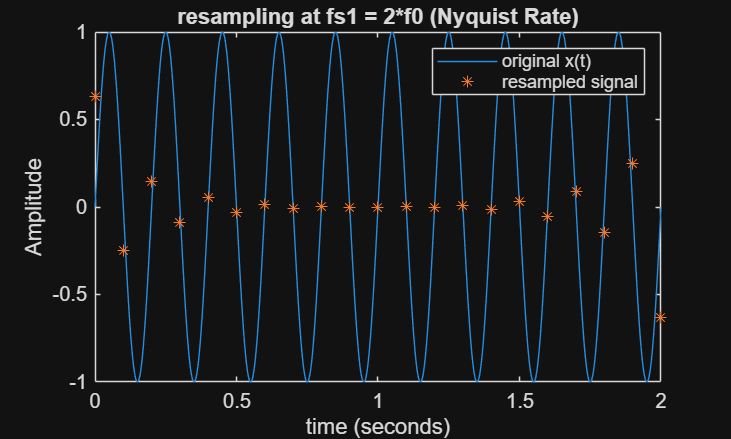

%case 1
plot(t,x);
hold on;
plot(t1_new,x1, "*")
legend("original x(t)","resampled signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("resampling at fs1 = 2*f0 (Nyquist Rate)");
hold off;

In case 2, we will compare the original signal to the case when the resampled signal is below the nyquist frequency (1.5 times the original frequency of x(t) rather than double).

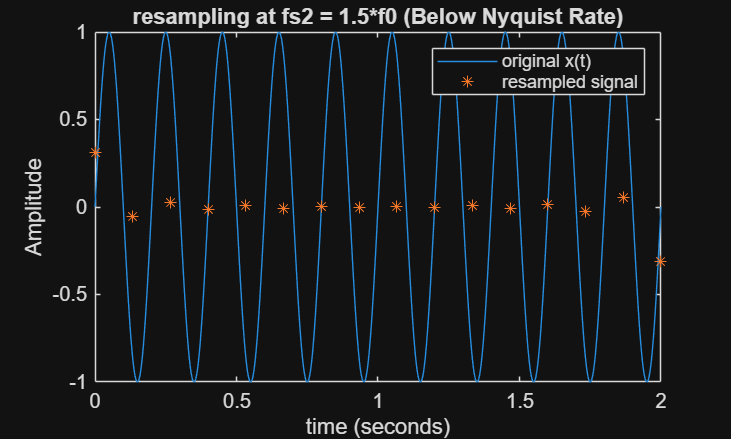

%case 2
plot(t,x);
hold on;
plot(t2_new,x2, "*")
legend("original x(t)","resampled signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("resampling at fs2 = 1.5*f0 (Below Nyquist Rate)");
hold off;

In case 3, we will compare the original signal to the case when the resampled signal is above at the nyquist frequency (quadruple the original frequency of x(t)).

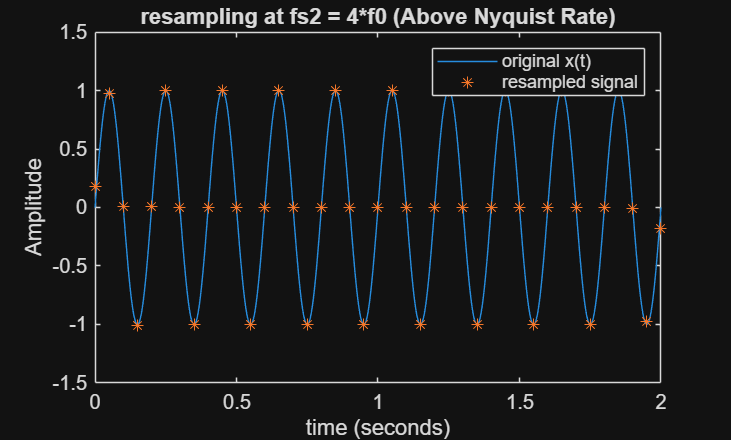

%case 3
plot(t,x);
hold on;
plot(t3_new,x3, "*")
legend("original x(t)","resampled signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("resampling at fs2 = 4*f0 (Above Nyquist Rate)");
hold off;

Now, we will attempt to reconstruct the original signal using each case, then plot it compared to the original on the same plot

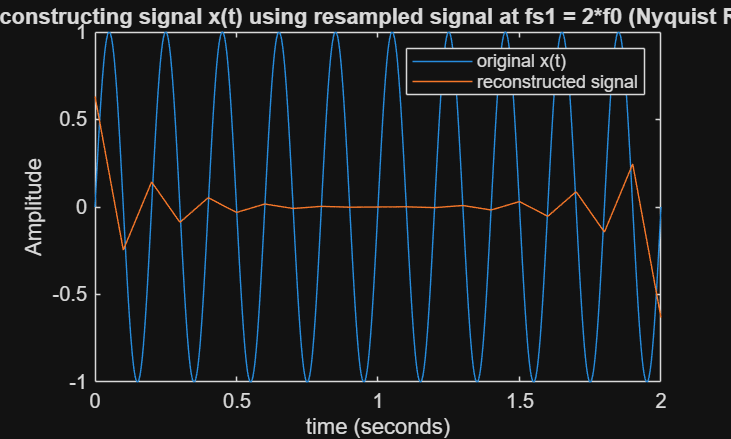

%case 1
x1_reconstruct = interp1(t1_new, x1, t);
plot(t,x);
hold on;
plot(t, x1_reconstruct);
legend("original x(t)","reconstructed signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("reconstructing signal x(t) using resampled signal at fs1 = 2*f0 (Nyquist Rate)");
hold off;

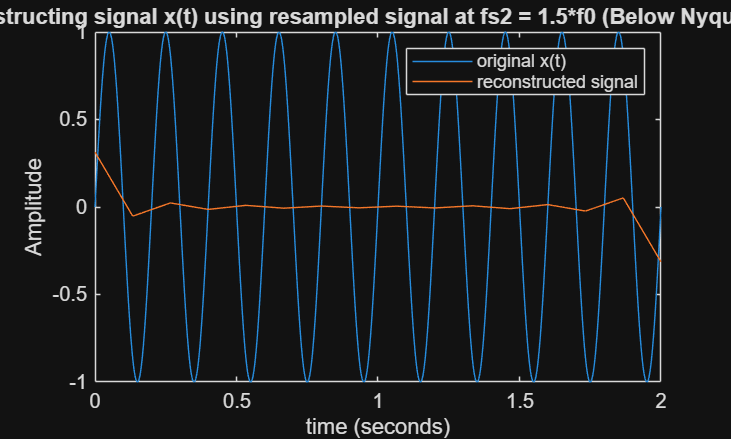


%case 2
x2_reconstruct = interp1(t2_new, x2, t);
plot(t,x);
hold on;
plot(t, x2_reconstruct);
legend("original x(t)","reconstructed signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("reconstructing signal x(t) using resampled signal at fs2 = 1.5*f0 (Below Nyquist Rate)");
hold off;

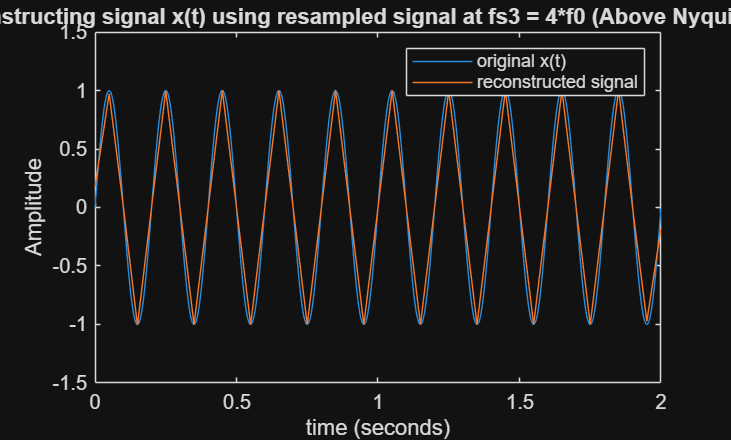


%case 3
x3_reconstruct = interp1(t3_new, x3, t);
plot(t,x);
hold on;
plot(t, x3_reconstruct);
legend("original x(t)","reconstructed signal");
xlabel("time (seconds)");
ylabel("Amplitude");
title("reconstructing signal x(t) using resampled signal at fs3 = 4*f0 (Above Nyquist Rate)");
hold off;

As is shown, reconstructing the signal at the nyquist frequency requires the interpolation of the signal based on 2 sampled data points per period of the original signal x(t). While this theoretically can allow for perfect reconstruction, this can cause issues, such as when the signal is sampled at the zero-crossing of the amplitude of x(t), leading to a "flat" reconstructed signal near the middle  between 0 and 2 seconds. While the initial beginning and end do show some of the original peaks and troughs, they are not as pronounced and die down as time goes on before reappearing at the end.

Similarly, reconstructing the signal based off of resampling below the nyquist frequency leads to even fewer data points, causing the same issues, but more pronounced due to the lack of data, with the reconstructed waveform appearing nearly completely flat with the exception of near the beginning and end of the plot.

In contrast, the reconstructed signal taken from the resampled signal above the nyquist frequency is nearly identical to the original waveform x(t); since it was resampled a 4 times the original frequency, there are 4 data points per period of the original signal x(t), allowing it to capture both the minimum, maximum, and zero crossings that allow the reconstructed signal to resemble the original.

## 3.1 MATLLAB Apps

### 3.1.1 MATLAB Apps Introduction, Summary, and Experience

I was introduced to MATLAB apps in the first video. I learned that there are a plethora of MATLAB Apps, each with their own functions and purposes, but all of which allow you to undergo tasks in MATLAB without needing to write any code.

I was taught how to see my available apps, import data into the app, and export the data.

I then moved on to how to clean data in MATLAB in order to prepare data for model development and analysis. First, data should be imported into the data cleaner app, then reformatted as needed, such as unstacking variables or separating data into separate columns. After the cleaning methods have been accepted and moved to the cleaning steps, it is now saved. The visualization of the data cleaner app can be used to view the data in various graphical forms. It is also possible to clean outliers within the data to remove them.

I then moved onto the signal analysis app video. Although the signal analyzer app was already somewhat covered in the onramping, the video provided a broader overview of the app’s capabilities. It went more into depth on the available features of the signal analyzer along with features of filtering, computing signal envelopes, and moving averages, among other things.

Finally, I was introduced to how to use the Signal Analyzer App. Unlike the videos, this was a written webpage explaining how to use the signal analyzer app. Using an example of analyzing a whale song recording, I was walked through how to preprocess a signal using a highpass filter for the whale song, how to extract specific regions of interest, and how to export the data as a MAT file.

### 3.1.2 Finding Delay Between Correlated Signals Example

The signal delay tutorial was a brief example on how to find the signal delay between two signals using two separate methods. The first method was to link the time between to signals in two separate displays, then pan to a salient feature. This will allow you to determine the delay between the two signals by virtue of them sharing the same time axis; the delay will be the difference from where that specific feature starts in either signal.

An alternative, much more intuitive method was also taught: using the cursors on the signal waveforms. Moving each of the cursors to either signals’ maximum, I was taught to find the time delay as the time difference between the two cursors.

In conclusion, this example provided me a brief but edifying example of how to find signal display, though nothing else. 